boat.L = 0.2;         % length in meters
boat.W = 0.2;         % width in meters
boat.HB = boat.W / 2;  % half breadth in meters
boat.D = 0.2;         % depth in meters

%boat.mass = 18;       % kg
boat.n = 2;         % shape parameter (dimensionless)
boat.density = 500; %kg/m^3

water_density = 1000; %kg/m^3
colormap;
clear mesh;

mesh.dy = 0.001;
mesh.dz = 0.001;
mesh.dx = 0.001;
mesh.ys = -boat.HB:mesh.dy:boat.HB;
mesh.zs = 0:mesh.dz:boat.D;
mesh.xs = -boat.L/2:mesh.dx:boat.L/2;
[mesh.xgrid, mesh.ygrid,mesh.zgrid] = meshgrid(mesh.xs, mesh.ys, mesh.zs);
[mesh.xgrid, mesh.ygrid] = meshgrid(mesh.xs, mesh.ys);

hull3D = computeHull3D(mesh,boat);
boat.num_cells = sum(hull3D(:));
boat.mass = boat.num_cells*boat.density*mesh.dx*mesh.dy*mesh.dz;
boat.mass_per_cell = boat.num_cells/boat.mass;

masses3D = hull3D*boat.mass_per_cell;
boat.COM = centerOfMass3D(masses3D, mesh)

boat = struct with fields:
                L: 0.2000
                W: 0.2000
               HB: 0.1000
                D: 0.2000
                n: 2
          density: 500
        num_cells: 7253296
             mass: 3.6266
    mass_per_cell: 2.0000e+06
              COM: [0 0 0.1051]


fun = @(d) massDiff3D(mesh, boat, 20, d);
d0 = boat.D/2;
d = fzero(fun, d0);
water = computeWater3D(d, theta, mesh);
sub_region = hull3D & water;
COB = centerOfMass3D(sub_region, mesh);

force = [0, -boiyant*sind(20), boiyant*cosd(20)]

force =          0  -12.1682   33.4318



hull3D = computeHull3D(mesh,boat);
boat.num_cells = sum(hull3D(:));
boat.mass = boat.num_cells*boat.density*mesh.dx*mesh.dy*mesh.dz;
boat.mass_per_cell = boat.num_cells/boat.mass;

masses3D = hull3D*boat.mass_per_cell;

boat.COM = centerOfMass3D(masses3D, mesh);
torques = [];
for theta = 0:5:160
    clear r
    fun = @(d) massDiff3D(mesh, boat, theta, d);
    d0 = boat.D/2;
    d = fzero(fun, d0);
    water = computeWater3D(d, theta, mesh);
    sub_region = hull3D & water;
    COB = centerOfMass3D(sub_region, mesh); %find COB
    
    
    r = COB - boat.COM;
    boiyant = boat.mass*9.81;
    force = [0, -boiyant*sind(theta), boiyant*cosd(theta)];
    moment = cross(r, force);
    
   
   
    torques = [torques; moment];
  
end

Exiting fzero: aborting search for an interval containing a sign change
    because no sign change is detected during search.
Function may not have a root.


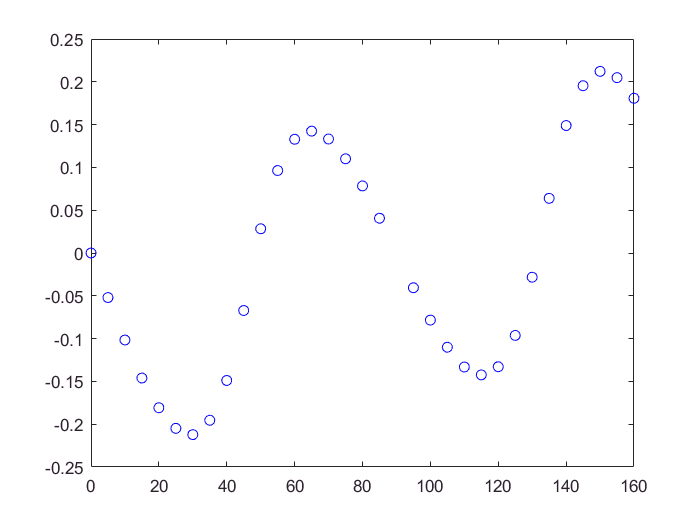

figure;
thetas = 0:5:160;
plot(thetas,torques(:,1), 'bo');

torques(:,1)

ans =    -0.0000
   -0.0520
   -0.1016
   -0.1461
   -0.1808
   -0.2048
   -0.2122
   -0.1954
   -0.1489
   -0.0672


function COM = centerOfMass3D(masses, mesh)
    M = sum(masses(:));
    x_masses = masses.*mesh.xgrid;
    x_COM = sum(x_masses(:))/M;
    y_masses = masses.*mesh.ygrid;
    y_COM = sum(y_masses(:))/M;
    
    z_masses = masses.*mesh.zgrid;
    z_COM = sum(z_masses(:))/M;
    COM = [x_COM,y_COM, z_COM];
end




function water = computeWater3D(d,theta,mesh)
    % water: compute the level of the water
    % d: depth of waterline in meters
    % theta: angle of waterline in degrees
    % mesh: structure containing ys and zgrid
    % returns: logical matrix
    
    y = mesh.ygrid;
    
    z = tand(theta) .* y + d;
    if theta <= 90
        water = mesh.zgrid <z;
    end
    if theta > 90
        water = mesh.zgrid > z;
    end
end


function hull = computeHull3D(mesh, boat)
    %computes a 3D hull with breadth B, depth D, and 
    %length L
    B = boat.W;
    D = boat.D;
    L = boat.L;
    center_station = (((2.*mesh.ygrid)./B).^20).*D;
    profile = (((2.*mesh.xgrid)./L).^20).*D;
    z = center_station + profile;
    hull = mesh.zgrid  >z;
end



function diff = massDiff3D(mesh,boat,theta,d)
    
%     for a value of theta and d, finds the differnce 
%     in boiyant and weight forces
    
    hull3D = computeHull3D(mesh, boat);
    boat.num_cells = sum(hull3D(:));
    boat.mass = boat.num_cells*mesh.dy*mesh.dz*mesh.dx*boat.density;
    water = computeWater3D(d, theta, mesh);
    sub_region = hull3D & water;
    
    displaced_water = sum(sub_region(:))*mesh.dx*mesh.dy*mesh.dz*1000;
    
    diff = boat.mass - displaced_water;
end

